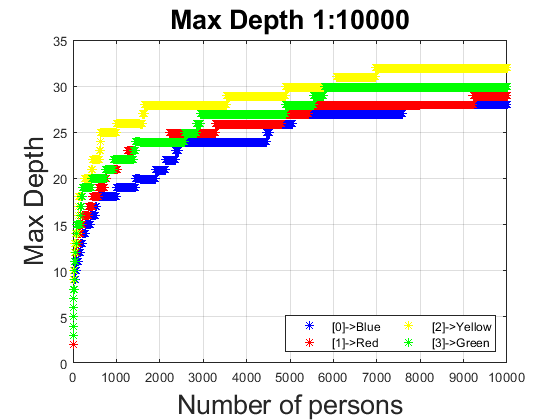

clear;
format long;
opengl('software');
opengl('save','software');

x = cell2mat(readcell('depthMax.txt','Delimiter','\t'));
x1=1:10000;
x2=10000:10900;
x3=10900:10990;
plot(x1,x(x1,1),'b*',x1,x(x1,2),'r*',x1,x(x1,3),'y*',x1,x(x1,4),'g*')
grid on
legend({'[0]->Blue','[1]->Red','[2]->Yellow','[3]->Green'} ,'Location','southeast','NumColumns',2)
title('Max Depth 1:10000','FontSize', 20)
xlabel('Number of persons','FontSize', 20)
ylabel('Max Depth','FontSize', 20)

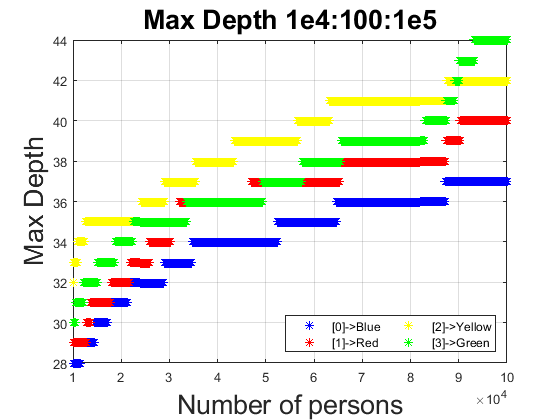



plot(10000:100:100000,x(x2,1),'b*',10000:100:100000,x(x2,2),'r*',10000:100:100000,x(x2,3),'y*',10000:100:100000,x(x2,4),'g*')
grid on
title('Max Depth 1e4:100:1e5','FontSize', 20)
xlabel('Number of persons','FontSize', 20)
ylabel('Max Depth','FontSize', 20)
legend({'[0]->Blue','[1]->Red','[2]->Yellow','[3]->Green'} ,'Location','southeast','NumColumns',2)

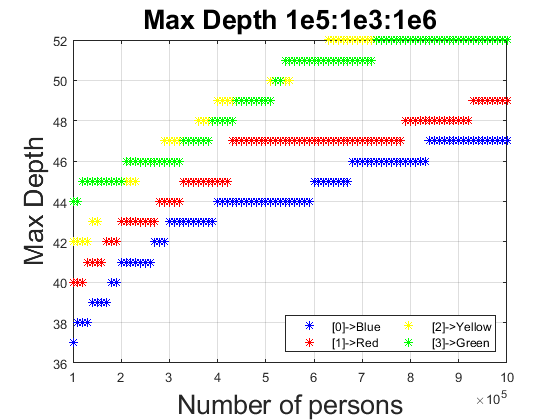


plot(100000:10000:1000000,x(x3,1),'b*',100000:10000:1000000,x(x3,2),'r*',100000:10000:1000000,x(x3,3),'y*',100000:10000:1000000,x(x3,4),'g*')
grid on
title('Max Depth 1e5:1e3:1e6','FontSize', 20)
xlabel('Number of persons','FontSize', 20)
ylabel('Max Depth','FontSize', 20)
legend({'[0]->Blue','[1]->Red','[2]->Yellow','[3]->Green'} ,'Location','southeast','NumColumns',2)

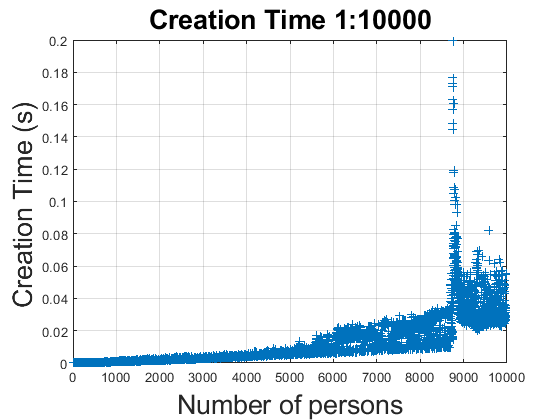



y = cell2mat(readcell('creationTime.txt','Delimiter','e'));
z=10.^y(:,2);
x= y(:,1).*z;
x1=1:10000;
x2=10000:10900;
x3=10900:10990;
plot(x1,x(x1),'+')
grid on
title('Creation Time 1:10000','FontSize', 20)
xlabel('Number of persons','FontSize', 20)
ylabel('Creation Time (s) ','FontSize', 20)

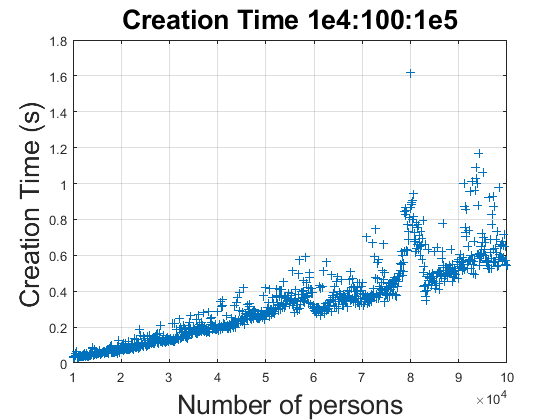


plot(10000:100:100000,x(x2),'+')
grid on
title('Creation Time 1e4:100:1e5','FontSize', 20)
xlabel('Number of persons','FontSize', 20)
ylabel('Creation Time (s) ','FontSize', 20)

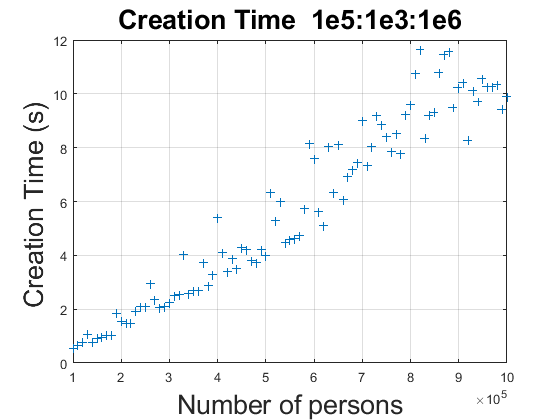


plot(100000:10000:1000000,x(x3),'+')
grid on
title('Creation Time  1e5:1e3:1e6','FontSize', 20)
xlabel('Number of persons','FontSize', 20)
ylabel('Creation Time (s) ','FontSize', 20)

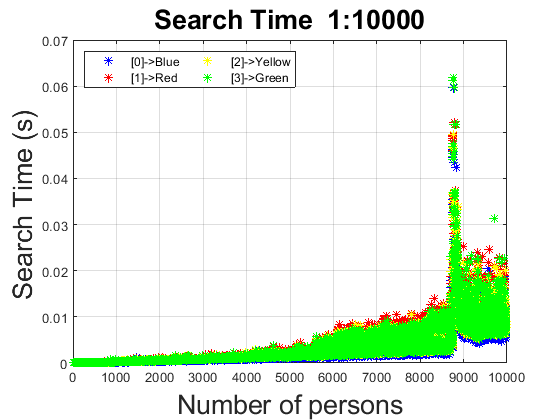


x = cell2mat(readcell('searchTime.txt','Delimiter','\t'));
x1=1:10000;
x2=10000:10900;
x3=10900:10990;
plot(x1,x(x1,1),'b*',x1,x(x1,2),'r*',x1,x(x1,3),'y*',x1,x(x1,4),'g*');
grid on
title('Search Time  1:10000','FontSize', 20)
xlabel('Number of persons','FontSize', 20)
ylabel('Search Time (s) ','FontSize', 20)
legend({'[0]->Blue','[1]->Red','[2]->Yellow','[3]->Green'} ,'Location','northwest','NumColumns',2)

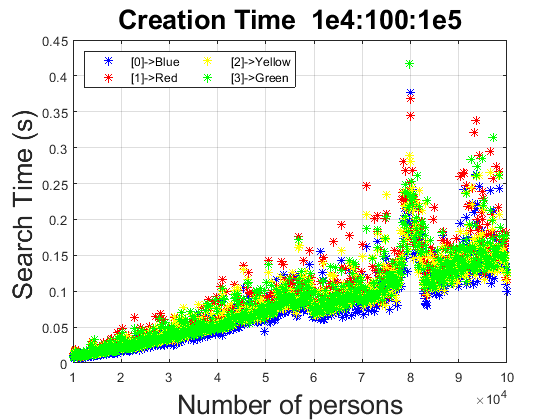


plot(10000:100:100000,x(x2,1),'b*',10000:100:100000,x(x2,2),'r*',10000:100:100000,x(x2,3),'y*',10000:100:100000,x(x2,4),'g*');
grid on
title('Creation Time  1e4:100:1e5','FontSize', 20)
xlabel('Number of persons','FontSize', 20)
ylabel('Search Time (s) ','FontSize', 20)
legend({'[0]->Blue','[1]->Red','[2]->Yellow','[3]->Green'} ,'Location','northwest','NumColumns',2)

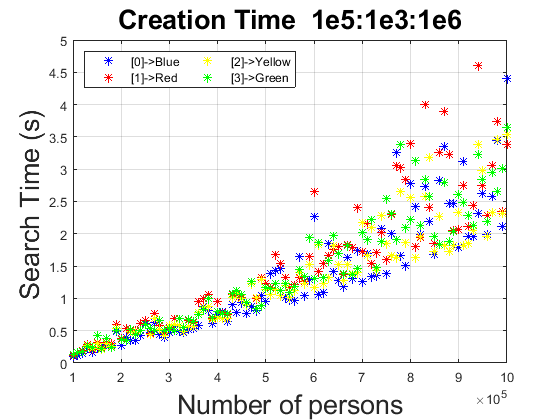


plot(100000:10000:1000000,x(x3,1),'b*',100000:10000:1000000,x(x3,2),'r*',100000:10000:1000000,x(x3,3),'y*',100000:10000:1000000,x(x3,4),'g*');
grid on
title('Creation Time  1e5:1e3:1e6','FontSize', 20)
xlabel('Number of persons','FontSize', 20)
ylabel('Search Time (s) ','FontSize', 20)
legend({'[0]->Blue','[1]->Red','[2]->Yellow','[3]->Green'} ,'Location','northwest','NumColumns',2)

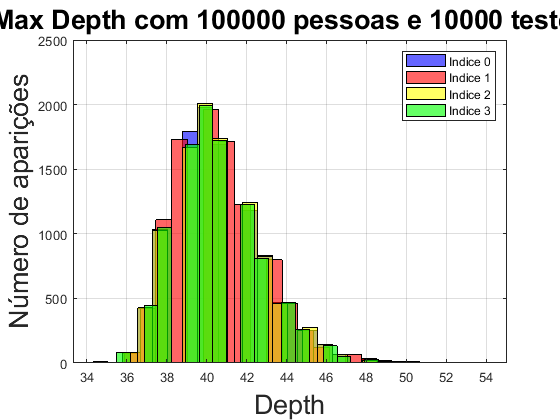





x = cell2mat(readcell('depthMax2.txt','Delimiter','\t'));
histogram(x(:,1),25,'FaceColor','blue')
hold on
histogram(x(:,2),25,'FaceColor','red')
histogram(x(:,3),25,'FaceColor','yellow')
histogram(x(:,4),25, 'FaceColor','green')
hold off
title('Max Depth com 100000 pessoas e 10000 testes','FontSize', 20);
ylabel('Número de aparições','FontSize', 20)
xlabel('Depth','FontSize', 20)
grid on
legend({'Indice 0','Indice 1','Indice 2','Indice 3'})

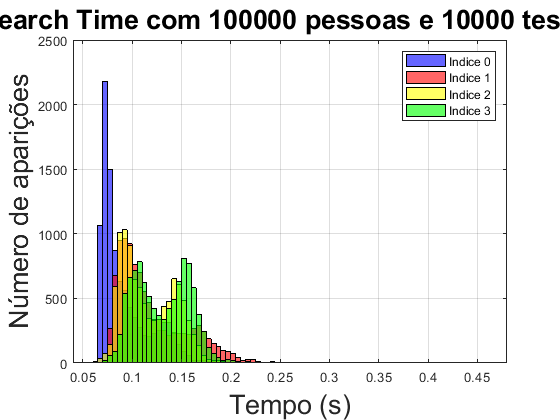



x = cell2mat(readcell('searchTime2.txt','Delimiter','\t'));
histogram(x(:,1),'FaceColor','blue')
hold on 
histogram(x(:,2),'FaceColor','red')
histogram(x(:,3),'FaceColor','yellow')
histogram(x(:,4),'FaceColor','green')
hold off
title('Search Time com 100000 pessoas e 10000 testes','FontSize', 20)
ylabel('Número de aparições','FontSize', 20)
xlabel('Tempo (s)','FontSize', 20)
grid on
legend({'Indice 0','Indice 1','Indice 2','Indice 3'})

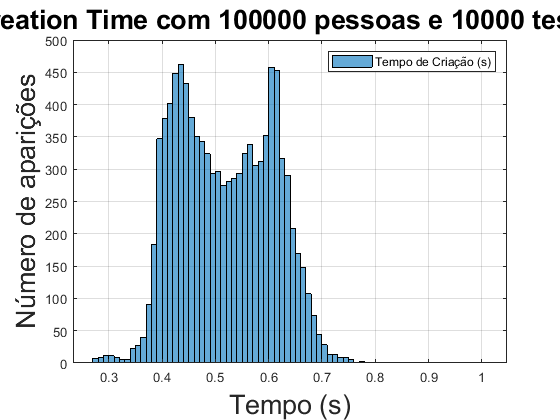





y = cell2mat(readcell('creationTime2.txt','Delimiter','e'));
z=10.^y(:,2);
x= y(:,1).*z;
histogram(x(:,1))
title('Creation Time com 100000 pessoas e 10000 testes','FontSize', 20)
ylabel('Número de aparições','FontSize', 20)
xlabel('Tempo (s)','FontSize', 20)
grid on
legend({'Tempo de Criação (s)'})